%load image
[fname, dname] = uigetfile('C:\Users\Bergles Lab\Desktop\New Folder (2)\*.tif','Multiselect','on');
[pathstr, name, ext] = fileparts([dname fname]);
X = loadTif([dname fname],16);
X = bleachCorrect(X,10);
X = normalizeImg(X,10,1);
[m,n,t] = size(X);

%%display image and get IC
figure;
imagesc(X(:,:,1));
h = imellipse();
wait(h);
indices = [];
indices = find(h.createMask);

ICsignal = zeros(1,t);
for i=1:t
    Xw = X(:,:,i);
    ICsignal(i) = squeeze(mean(Xw(indices)));
end

reX = single(reshape(X,m*n,t));

corrmat = corr(ICsignal', reX');
corrmat = reshape(corrmat,m,n);
figure; imagesc(corrmat);
truesize;

ACindex = find(corrmat > 0.7)
ACindex = ACindex(ACindex < 3.5e4)
temp = zeros(m,n);
temp(ACindex) = 1;
figure; imagesc(temp);

ACsignal = zeros(1,t);
for i=1:t
    Xw = X(:,:,i);
    ACsignal(i) = squeeze(mean(Xw(ACindex)));
end

expt.name = name;
expt.corrmat = corrmat;
expt.ACindex = ACindex;
expt.ICsignal = ICsignal;
expt.ACsignal = ACsignal;

nm = 100;
nn = 100;
h = imrect(gca,[0 0 nm nn]);
wait(h);
indices = [];
indices = find(h.createMask);

ACpicture = single(zeros(nm,nn,t));
parfor i=1:t
    Xw = X(:,:,i);
    ACpicture(:,:,i) = single(reshape(Xw(indices),100,100));
end



%%Load image to register
[fname, dname] = uigetfile('C:\Users\Bergles Lab\Desktop\New Folder (2)\*.tif','Multiselect','on');
[pathstr, name, ext] = fileparts([dname fname]);
Xreg = loadTif([dname fname],16);
Xreg = bleachCorrect(Xreg,10);


%%register that bad boy
temp = {};
tforms = [];
norms = [];
regd =[];
regto = fft2(mean(Xreg,3));
t = size(Xreg,3);
parfor i = 1:t
    [output, Greg] = dftregistration(regto,fft2(Xreg(:,:,i)),1)
    norms(i) = norm([1 0 output(3); 0 1 output(4); 0 0 1],2);
end

hit = zeros(size(norms));
for i = 1:t
    if norms(i) > 1
        %look 20 ahead
        if i < t-20
            if sum(norms(i+1:i+20)-1) > 0
                hit(i:i+20) = 1;
            elseif hit(i-1) == 1
                hit(i) = 1;
                hit(i+1:i+20)=0;
            else
                hit(i) = 0;
            end
        end
    end
end

figure; plot(norms-1); hold on; plot(hit)
labs = bwlabel(hit);

%%
holddata = [];
figure;
timepad = 60
for i=1:max(labs)
    index = find(labs == i,1)
    if index - timepad > 0 & index + timepad <= t
        ACdata(:,i) = ACsignal(index-timepad:index+timepad);
        ICdata(:,i) = ICsignal(index-timepad:index+timepad);
         plot(ACsignal(index-timepad:index+timepad)); hold on;
    end
end

figure;
plot(mean(ACdata,2),'linewidth',2,'Color','k'); hold on;
plot(mean(ICdata,2),'linewidth',2,'Color','r'); 
ylim([0 0.5])
expt.norms = norms;
expt.hits = hit;
expt.labels = labs;
expt.ACdata = ACdata;
expt.meanAC = mean(ACdata,2);
expt.ICdata = ICdata;
expt.meanIC = mean(ICdata,2);


%%save data
sname = regexp(fname,'(Experiment-\d\d\d)','tokens')
save([dname sname{1}{1} '_data.mat'],'expt','-mat')


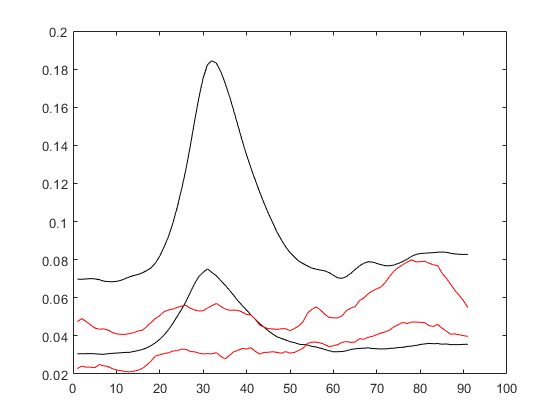

ans = 'M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\IC_A1_Window\Experiment-132_data.mat'

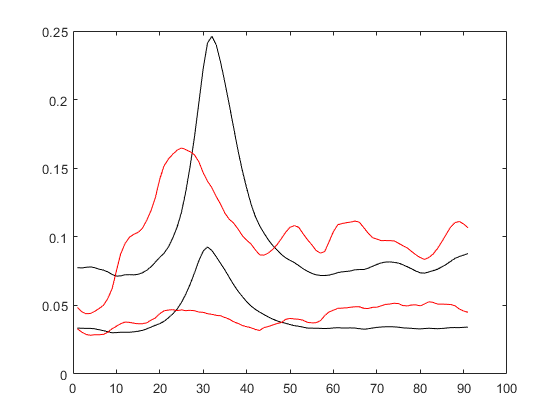

ans = 'M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\IC_A1_Window\Experiment-1440_data.mat'

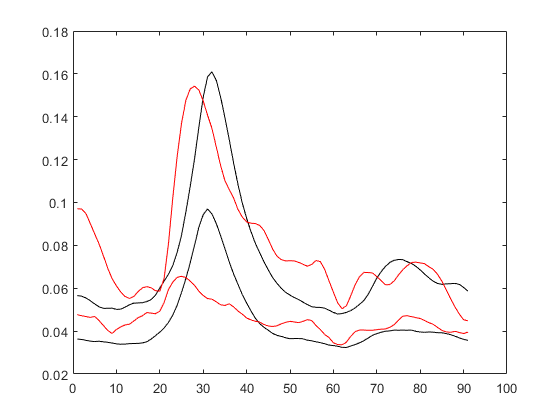

ans = 'M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\IC_A1_Window\Experiment-1538_data.mat'

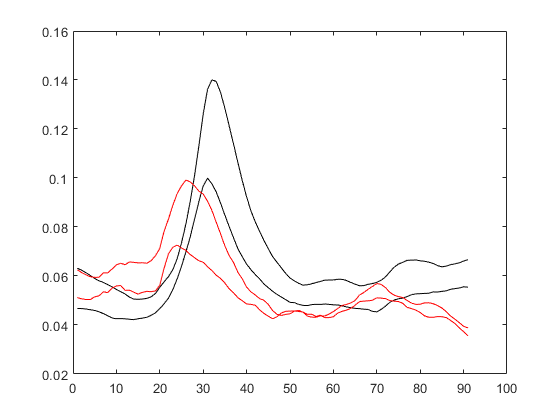

ans = 'M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\IC_A1_Window\Experiment-1543_data.mat'

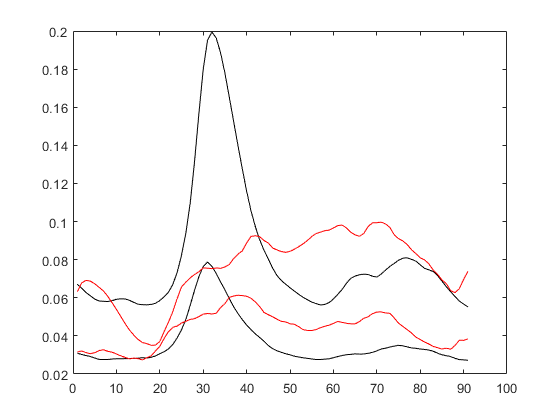

ans = 'M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\IC_A1_Window\Experiment-1549_data.mat'

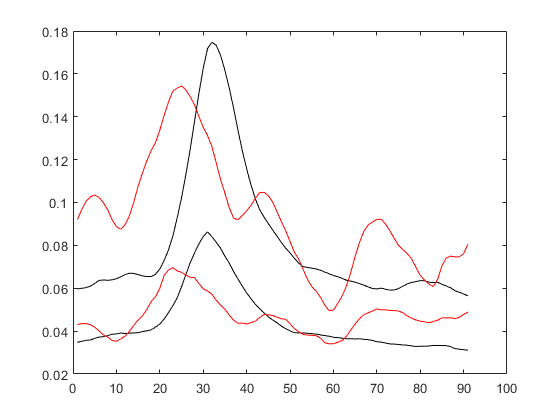

ans = 'M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\IC_A1_Window\Experiment-154_data.mat'

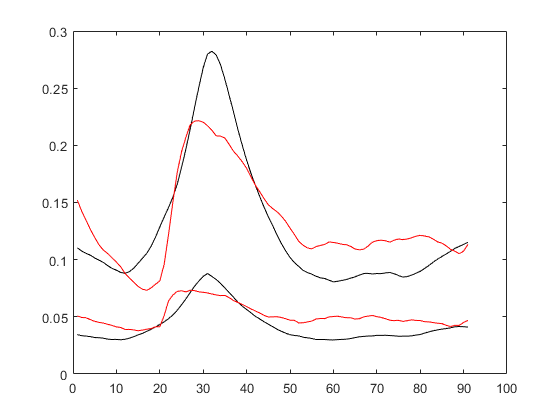

ans = 'M:\Bergles Lab Data\Papers\In Vivo Paper\Figure 4 - Auditory Cortex\Data\IC_A1_Window\Experiment-1611_data.mat'

%Add analysis of all events

%load cells
cellList = loadFileList('.\Data\IC_A1_Window\*data.mat');
threshold = 0.03;

ICeventsIC = [];
ACeventsIC = [];
%cellStruct = struct();

for i = 1:size(cellList,1)
   [h] = load(cellList{i});
   names = fieldnames(h);
   temp = h.(names{1});
   time = 1:1:size(temp.ICsignal,2);
   
   %Analyze events based on IC events
   [pks,locs] = findpeaks(temp.ICsignal,time,'MinPeakProminence',threshold);
   temp.ICeventFreq = size(locs,2)/(time(end)/10)*60;
   ICeventsIC = [];
   ACeventsIC = [];
   %figure; findpeaks(temp.ICsignal,time,'MinPeakProminence',threshold)
   time_before = 30;
   time_after = 60;
   locs = locs(locs > time_before & locs < (time(end)-time_after));

   for j = 1:size(locs,2)
       ICeventsIC(j,:) = temp.ICsignal(:,locs(j)-time_before:locs(j)+time_after);
       ACeventsIC(j,:) = temp.ACsignal(:,locs(j)-time_before:locs(j)+time_after);
   end
   temp.ICeventsIC = ICeventsIC;
   temp.ACeventsIC = ACeventsIC;
   temp.ICeventlocs = locs;
   temp.ICeventpeaks = pks;
   
   %Get frequency of AC events
   [pks,locs] = findpeaks(temp.ACsignal,time,'MinPeakProminence',threshold);
   temp.ACeventFreq = size(locs,2)/(time(end)/10)*60;
   
   %%movement analysis
    movements = max(temp.labels);
    boutlength = [];
    for j = 1:movements
        boutlength(j) = size(find(temp.labels == j),2)/10;
    end
    temp.mvmtFreq = movements/(time(end)/10)*60;
    temp.boutlengths = boutlength;
    
    labs = temp.labels;
    ACdata = [];
    ICdata = []; 
    mvmttimes = [];
    time_before = 20;
    time_after = 70;
    for j=1:max(labs)
        index = find(labs == j,1);
        
        if index - time_before > 0 & index + time_after <= time(end)
            mvmttimes(j,:) = [index - time_before index + time_after];
            ACdata(:,j) = temp.ACsignal(index-time_before:index+time_after);
            ICdata(:,j) = temp.ICsignal(index-time_before:index+time_after);
        end
        
        temp.ACdata = ACdata;
        temp.ICdata = ICdata;
        temp.meanAC = mean(ACdata,2);
        temp.meanIC = mean(ICdata,2);
        temp.mvmtTimes = mvmttimes;
    end
   figure; plot(mean(ICeventsIC,1),'Color','k'); hold on; plot(mean(ACeventsIC,1),'Color','k');
   plot(temp.meanAC,'Color','r'); plot(temp.meanIC,'Color','r');
   
   expt = temp;
   save(cellList{i},'expt','-mat')
   cellList{i}
end

## Correlation Analysis

mvmt_corrs = [];
IC_corrs = [];
for i = 1:size(cellStruct,2)
    temp = cellStruct(i);
    if i == 4
        temp.ICdata = temp.ICdata(:,2:end);
        temp.ACdata = temp.ACdata(:,2:end);
    end
    mvmt_corrs(i) = mean(max(corr(temp.ICdata(15:60,:),temp.ACdata(15:60,:)).*eye(size(temp.ICdata,2))));
    IC_corrs(i) = mean(max(corr(temp.ICeventsIC(:,15:60)',temp.ACeventsIC(:,15:60)').*eye(size(temp.ICeventsIC,1))));
end

[h,p] = ttest2(mvmt_corrs,IC_corrs)

h = 0

p = 0.2003

mean(mvmt_corrs)

ans = 0.7115

mean(IC_corrs)

ans = 0.7966


mvmt_xcorrs = [];
IC_xcorrs = [];
for i = 1:size(cellStruct,2)
    temp = cellStruct(i);
    if i == 4
        temp.ICdata = temp.ICdata(:,2:end);
        temp.ACdata = temp.ACdata(:,2:end);
    end
    
    mvmtcorrs = [];
    for j = 1:size(temp.ICdata,2)
        mvmtcorrs(j) = xcorr([temp.ICdata(:,j)-mean(temp.ICdata(:,j))],[temp.ACdata(:,j)-mean(temp.ACdata(:,j))],0);
    end
    
    ICcorrs = [];
    for j = 1:size(temp.ICeventsIC,1)
        ICcorrs(j) = xcorr([temp.ICeventsIC(j,:)-mean(temp.ICeventsIC(j,:))]',[temp.ACeventsIC(j,:)-mean(temp.ACeventsIC(j,:))]',0);
    end
    
    mvmt_xcorrs(i) = mean(mvmtcorrs);
    IC_xcorrs(i) = mean(ICcorrs);
end

[h,p] = ttest2(mvmt_xcorrs,IC_xcorrs)

h = 1

p = 0.0486

mean(mvmt_xcorrs)

ans = 0.1024

mean(IC_xcorrs)

ans = 0.1733